clc;clear;close all
c=imread('cameraman.tif');
cmax = nlfilter(c,[3,3],'max(x(:))');
imshow(cmax)
cmin = nlfilter(c,[3,3],'min(x(:))');
imshow(cmin)
c0=colfilt(c,[3,3],'sliding',@max);
imshow(c0)
cord=ordfilt2(c,9,ones(3,3));
imshow(cord)


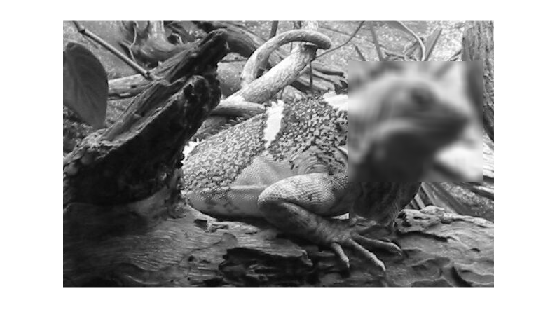

clc;clear;close all
i=imread('iguana.tif');
roi=roipoly(i,[406 600 600 406],[58 58 231 231]);

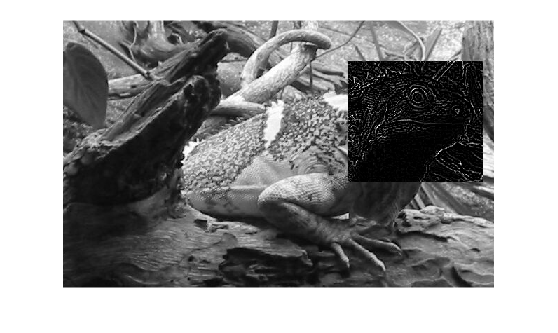

u=fspecial('log');
mu=roifilt2(u,i,roi);
imshow(mu)

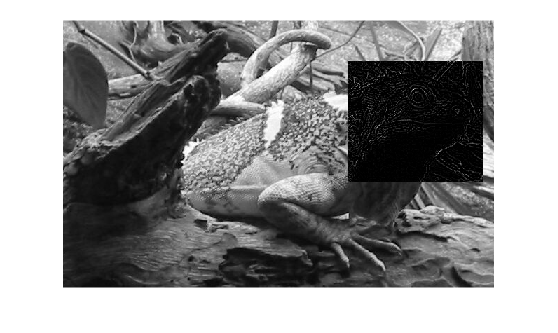

u=fspecial('laplacian');
mu=roifilt2(u,i,roi);
imshow(mu)

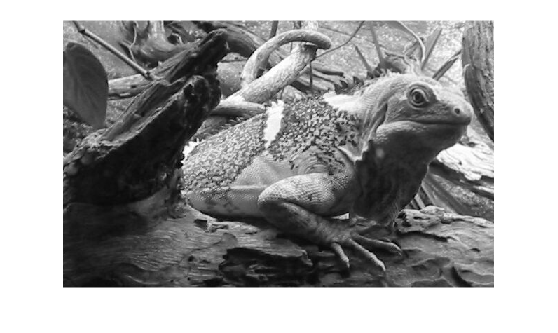

u=fspecial('gaussian');
mu=roifilt2(u,i,roi);
imshow(mu)